%% contact function for two identical spheroids
%已知椭球相切，求约束关系

syms lambda rA rB R1 R2 R3 uA3 uB3 ;

rA=[-1;2;4];
uA3=[0;1;1]; 
rB=[2; -3; 4];
uB3=[1;-1;0];
% center and direction of spheroids
for e=0.2:0.1:3 %离心率
    R1=2;
    R3=e*R1; %椭球半轴长，R1=R2,R3是polar axis
    n=0.02; %模拟的步长精度

    miu2=cont(rA,rB,R1,R3,uA3,uB3);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=e*R1;
        miu2=cont(rA,rB,R1,R3,uA3,uB3);
    end
    
    while miu2<1
        R1=R1-n;
        R3=e*R1;
        miu2=cont(rA,rB,R1,R3,uA3,uB3);
    end
    [e,R1,miu2]
    hold on
    scatter(R1,R1*e,'b')
    xlabel('R1'); ylabel('R3');
end

ans =     0.2000   16.5800    1.0004


ans =     0.3000   10.9800    1.0023


ans =     0.4000    8.1600    1.0044


ans =     0.5000    6.4600    1.0037


ans =     0.6000    5.3000    1.0075


ans =     0.7000    4.4800    1.0015


ans =     0.8000    3.8400    1.0017


ans =     0.9000    3.3200    1.0083


ans =     1.0000    2.9000    1.0107


ans =     1.1000    2.5600    1.0034


ans =     1.2000    2.2600    1.0049


ans =     1.3000    2.0000    1.0100


ans =     1.4000    1.7800    1.0136


ans =     1.5000    1.6000    1.0090


ans =     1.6000    1.4400    1.0152


ans =     1.7000    1.3000    1.0289


ans =     1.8000    1.2000    1.0106


ans =     1.9000    1.1000    1.0189


ans =     2.0000    1.0200    1.0152


ans =     2.1000    0.9400    1.0346


ans =     2.2000    0.8800    1.0310


ans =     2.3000    0.8200    1.0457


ans =     2.4000    0.7800    1.0254


ans =     2.5000    0.7400    1.0176


ans =     2.6000    0.7000    1.0220


ans =     2.7000    0.6600    1.0388


ans =     2.8000    0.6400    1.0033


ans =     2.9000    0.6000    1.0415


ans =     3.0000    0.5800    1.0212


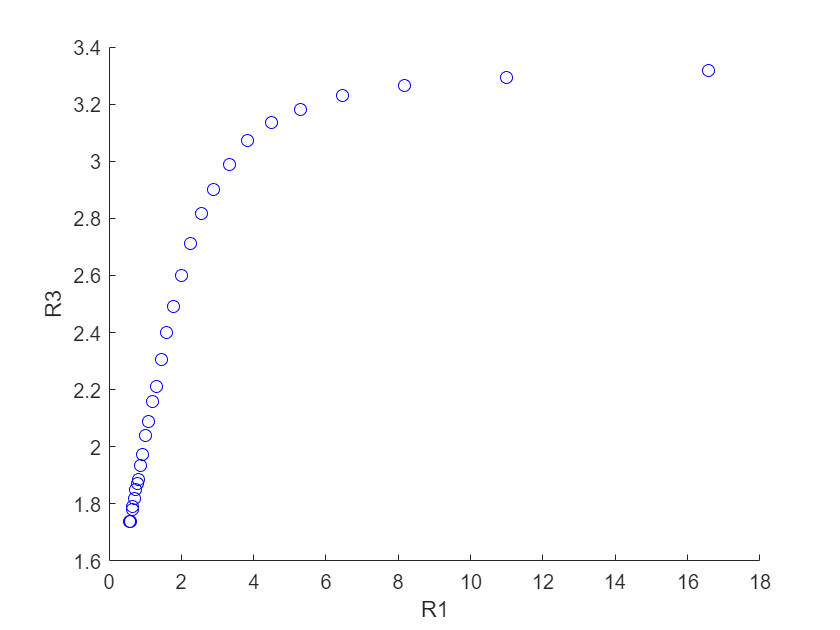

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end


